clear
clf

load('data/gauntlet_scans.mat')
warning('off','all')

r = r_all(:,1);
theta = theta_all(:,1);

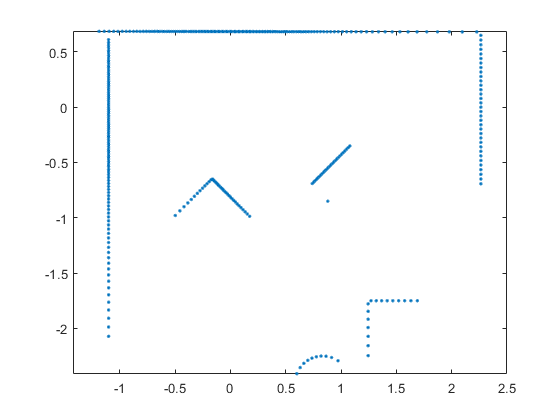

r_clean_index = find((r ~= 0) & (r < 3));
r_clean = r(r_clean_index);
theta_clean = theta(r_clean_index);
[x, y] = pol2cart(theta_clean, r_clean);
points = [x y];
clf
plot(x, y, '.')
axis equal

% find lines
d = 0.01

d = 0.0100

n = 1000

n = 1000

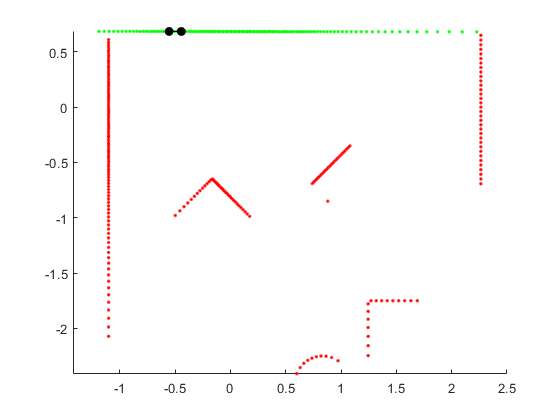

[endpoints, inliers1, outliers1, m, b] = ransac_line_fit(points, d, n, 1);

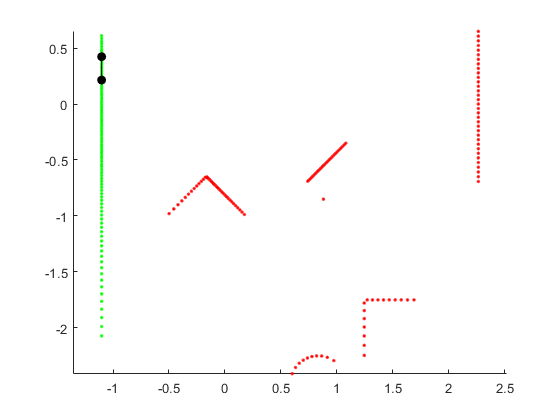

[endpoints, inliers2, outliers2, m, b] = ransac_line_fit(outliers1, d, n, 1);

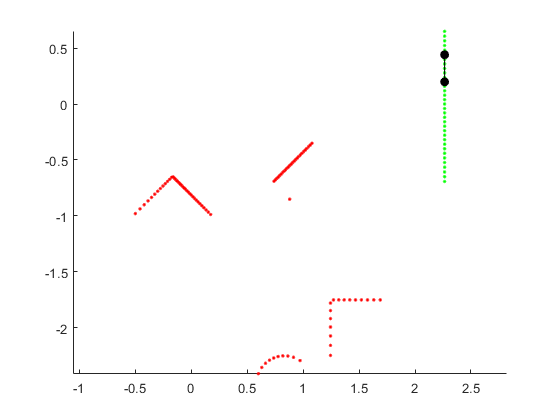

[endpoints, inliers3, outliers3, m, b] = ransac_line_fit(outliers2, d, n, 1);

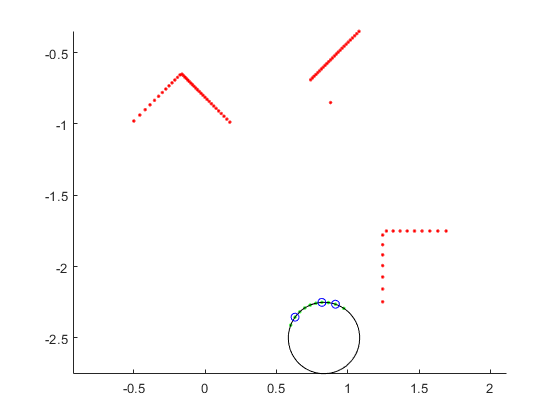

d = 0.01;
n = 5000;
r_max = 0.3;
[endpoints, inliers4, outliers4, near_matches4, center, rad] = ransac_circle_fit(outliers3, r_max, d, n, 1);